clear;
load("bridge_of_doom_data.mat")


%WHEEL SPEEDS
VL = diff(encoder_data(:, 1:2));
VR = diff(encoder_data(:, [1 3]));
row_length = size(VL, 1);
encoder_time = encoder_data(1:row_length, 1);

%ANGULAR VELOCITY AND SPEED
ANGULAR = (VR(:, 2) - VL(:, 2))./0.245;
SPEED = (VR(:, 2) + VL(:, 2))./2;

%POSITION
POSITIONX = [subs(ri, u, 0)];
POSITIONY = [subs(rj, u, 0)];
t_hat_zero = subs(t_hat, u, 0);
cur_angle = atan(t_hat_zero(2)/t_hat_zero(1));

for i=1:row_length
    cur_angle = cur_angle + ANGULAR(i);
    POSITIONY(i+1) = POSITIONY(i) + sin(cur_angle) * SPEED(i);
    POSITIONX(i+1) = POSITIONX(i) + cos(cur_angle) * SPEED(i);
end

theta = linspace(0, 3.2, 200);
x = 0.3960 * cos(2.65 * (theta + 1.4));
y = -0.99 * sin(theta + 1.4);

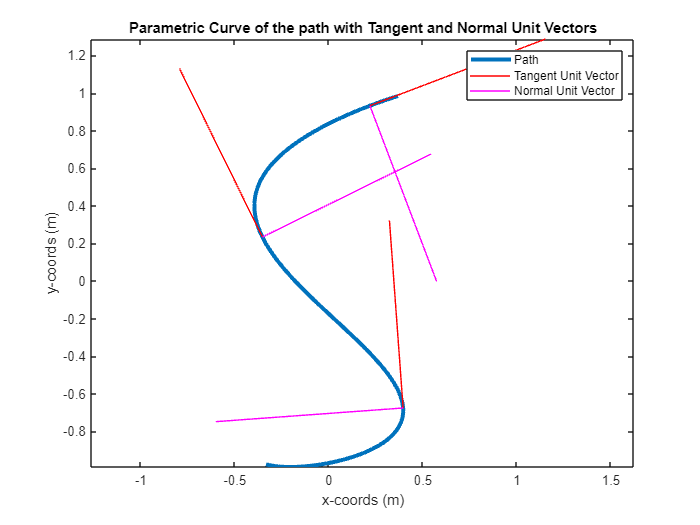


% PLOTTING PATH and T and N UNIT VECTORS
clf;
plot(x,y, LineWidth=3); hold on;
axis equal;

for i = 1:3
    time = i * 9;
    start = [subs(ri, u, time) subs(rj, u, time)];
    t_hat_at_time = subs(t_hat, u, time);
    n_hat_at_time = subs(n_hat, u, time);
    x_t_vec = [start(1) start(1)+t_hat_at_time(1)];
    y_t_vec = [start(2) start(2)+t_hat_at_time(2)];
    x_n_vec = [start(1) start(1)+n_hat_at_time(1)];
    y_n_vec = [start(2) start(2)+n_hat_at_time(2)];
    
    plot(x_t_vec, y_t_vec, "r-");
    plot(x_n_vec, y_n_vec, "m-");
end
legend("Path", "Tangent Unit Vector", "Normal Unit Vector");
xlabel("x-coords (m)")
ylabel("y-coords (m)")
title("Parametric Curve of the path with Tangent and Normal Unit Vectors")
hold off;

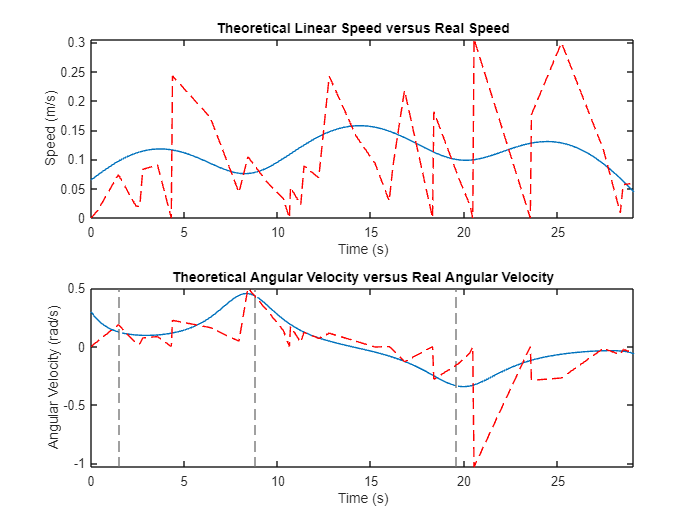


% PLOTTING LINEAR SPEED AND ANGULAR VELOCITY
clf;
subplot(2, 1, 1);
fplot(dsdt, [0, drivetime]); hold on;
plot(encoder_time, SPEED, "r--"); hold off;
title("Theoretical Linear Speed versus Real Speed")
xlabel("Time (s)")
ylabel("Speed (m/s)")
subplot(2, 1, 2);
fplot(omega, [0, drivetime]); hold on;
title("Theoretical Angular Velocity versus Real Angular Velocity")
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
plot(encoder_time, ANGULAR, "r--"); hold off;

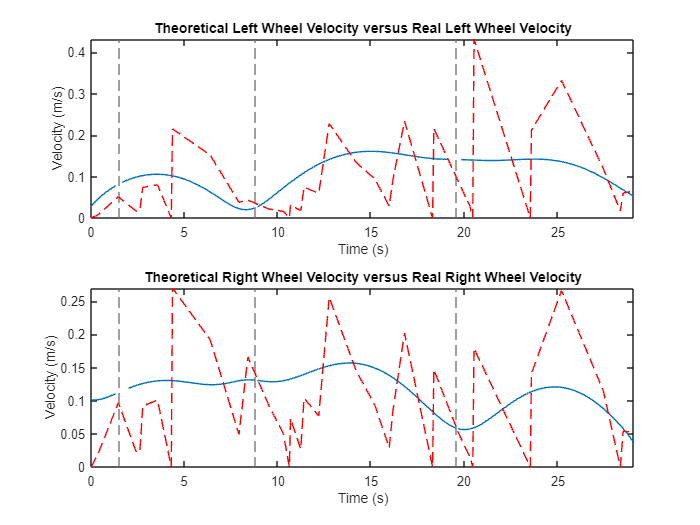


% PLOTTING WHEEL VELOCITIES
clf;
subplot(2, 1, 1);
fplot(v_l, [0 drivetime]); hold on;
plot(encoder_time, VL(:, 2), "r--"); hold off;
title("Theoretical Left Wheel Velocity versus Real Left Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
subplot(2, 1, 2);
fplot(v_r, [0 drivetime]); hold on;
plot(encoder_time, VR(:, 2), "r--"); hold off;
title("Theoretical Right Wheel Velocity versus Real Right Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")

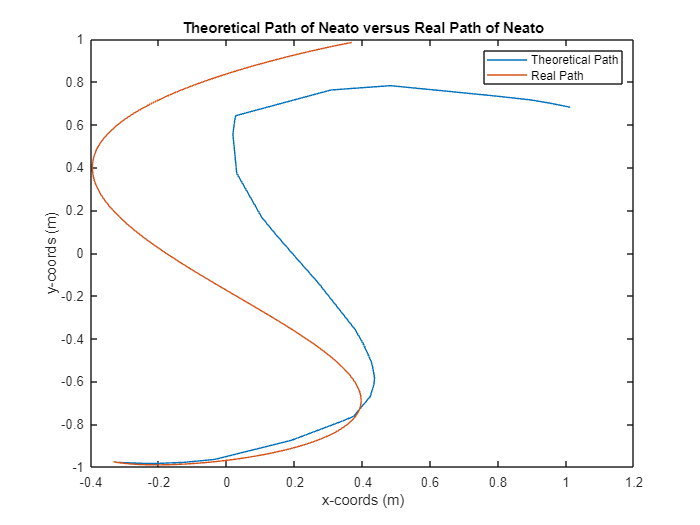


% PLOTTING THEORETICAL PATH vs. REAL PATH
clf;
plot(POSITIONX, POSITIONY); hold on;
plot(x, y);
title("Theoretical Path of Neato versus Real Path of Neato")
legend("Theoretical Path", "Real Path");
xlabel("x-coords (m)")
ylabel("y-coords (m)")